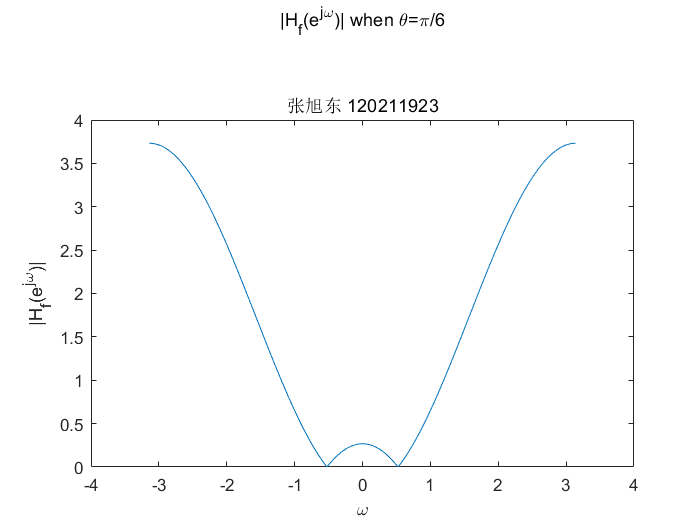

%7.3.1
omega1=-pi:0.01:pi;
z=exp(1j*omega1);
sita=[pi/6 pi/3 pi/2];

H1=1-2*cos(sita(1)).*z.^(-1)+z.^(-2);
H2=1-2*cos(sita(2)).*z.^(-1)+z.^(-2);
H3=1-2*cos(sita(3)).*z.^(-1)+z.^(-2);

plot(omega1,abs(H1));
xlabel("\omega");
ylabel("|H_{f}(e^j^\omega)|");
title(["|H_{f}(e^j^\omega)| when \theta=\pi/6" newline "张旭东 120211923"]);
axis([-4 4 0 4]);

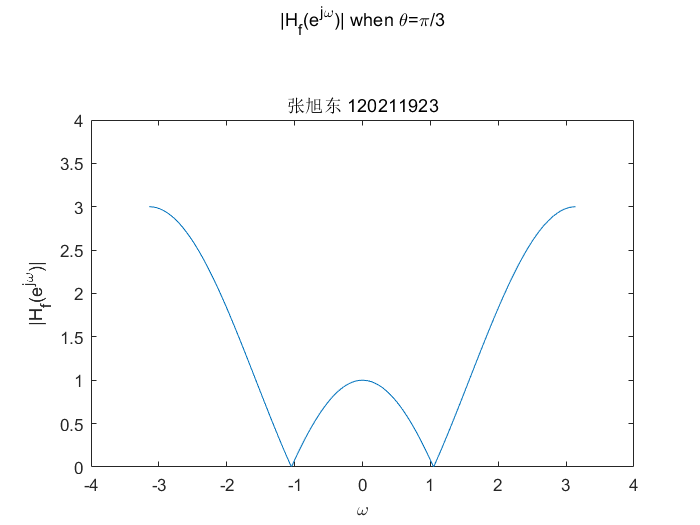


plot(omega1,abs(H2));
xlabel("\omega");
ylabel("|H_{f}(e^j^\omega)|");
title(["|H_{f}(e^j^\omega)| when \theta=\pi/3" newline "张旭东 120211923"]);
axis([-4 4 0 4]);

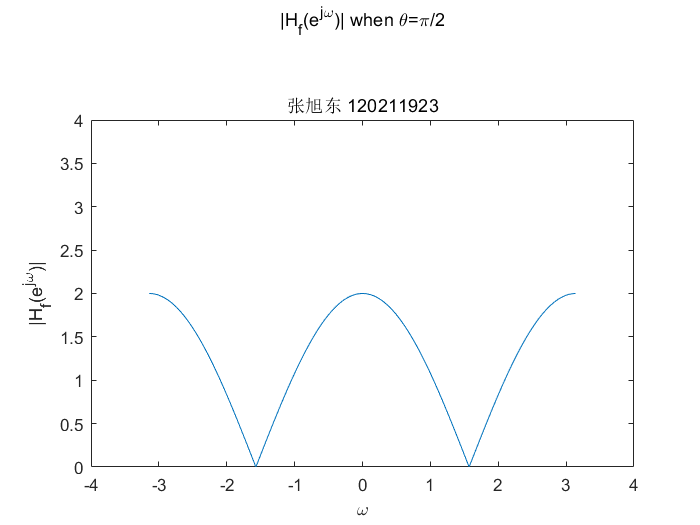


plot(omega1,abs(H3));
xlabel("\omega");
ylabel("|H_{f}(e^j^\omega)|");
title(["|H_{f}(e^j^\omega)| when \theta=\pi/2" newline "张旭东 120211923"]);
axis([-4 4 0 4]);

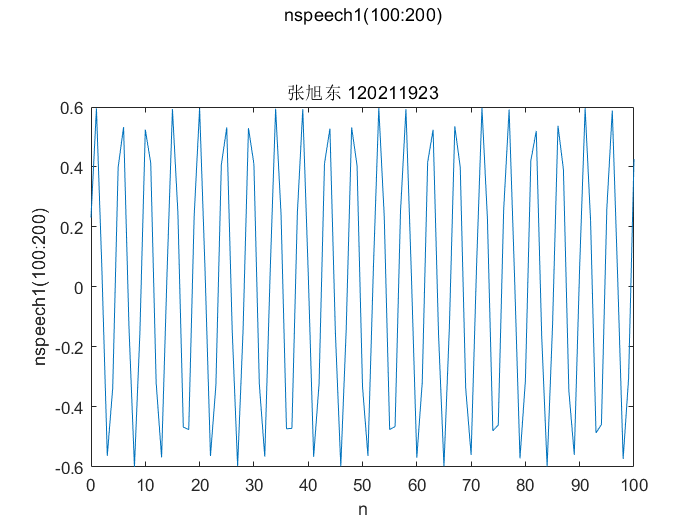


%7.3.2
load nspeech1.mat
sound(nspeech1);
plot(0:100,nspeech1(100:200));
xlabel("n");
ylabel("nspeech1(100:200)");
title(["nspeech1(100:200)" newline "张旭东 120211923"]);

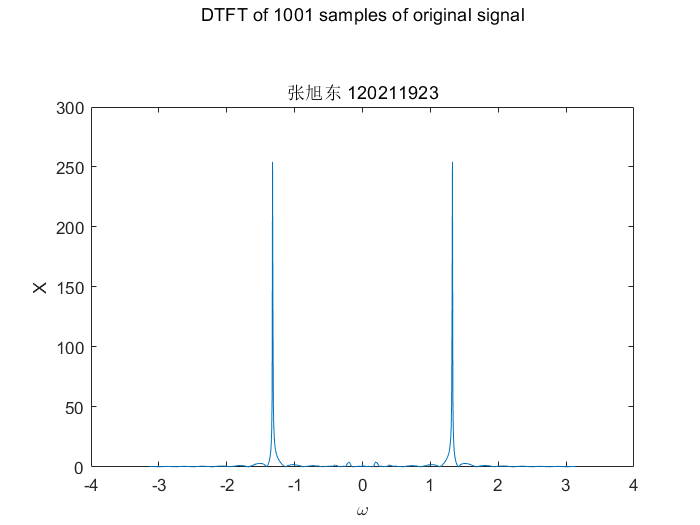


[X1,omega2]=DTFT(nspeech1(100:1100),1024);
plot(omega2,abs(X1));
xlabel("\omega");
ylabel("X");
title(["DTFT of 1001 samples of original signal" newline "张旭东 120211923"]);



[Xmax,Imax]=max(abs(X1))

Xmax = 254.2287

Imax = 297

disp(-pi+(Imax-1)*2*pi/1024)

   -1.3254



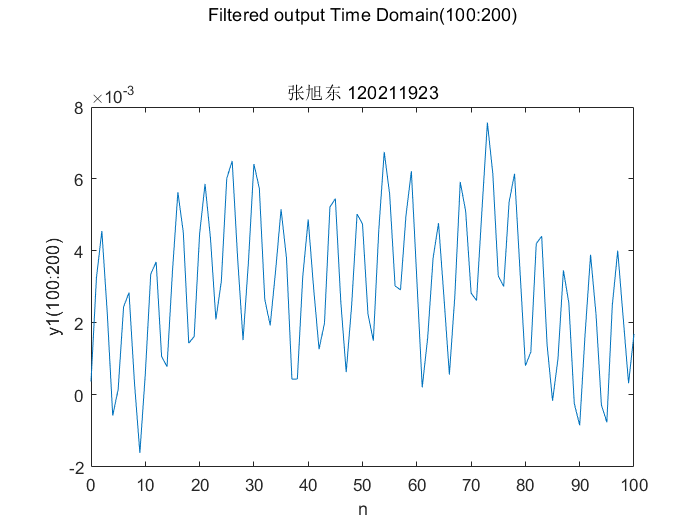


y1=FIRfilter(nspeech1,1.3254);
sound(y1);
plot(0:100,y1(100:200));
xlabel("n");
ylabel("y1(100:200)");
title(["Filtered output Time Domain(100:200)" newline "张旭东 120211923"]);

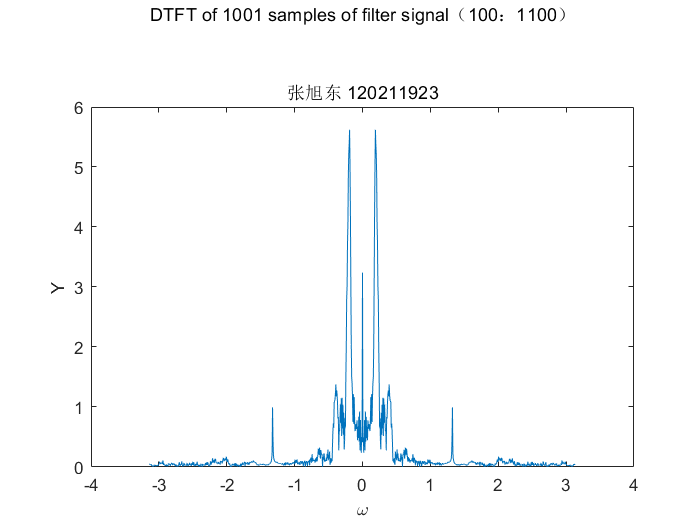


[Y1,omegay]=DTFT(y1(100:1100),0);
plot(omegay,abs(Y1));
xlabel("\omega");
ylabel("Y");
title(["DTFT of 1001 samples of filter signal（100：1100）" newline "张旭东 120211923"]);

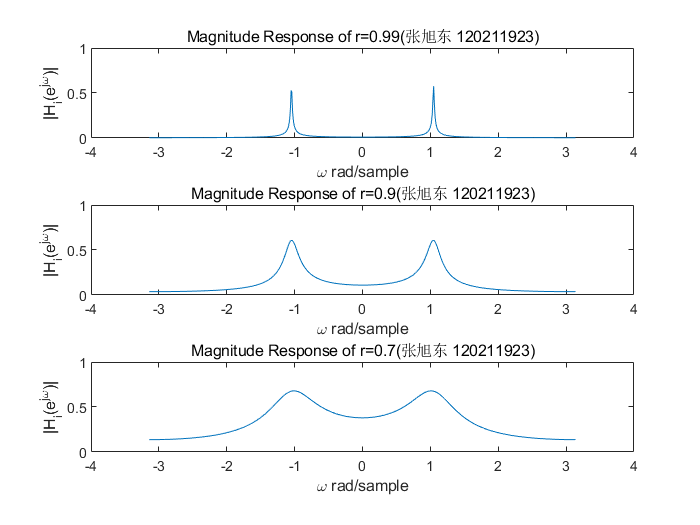


%7.4.1
w=-pi:0.01:pi;
r1=0.99;
numr1=1-r1;
denr1=[1 -2*r1*cos(pi/3) r1*r1];
[magr1,phaser1]=FreRes(numr1,denr1);

r2=0.9;
numr2=1-r2;
denr2=[1 -2*r2*cos(pi/3) r2*r2];
[magr2,phaser2]=FreRes(numr2,denr2);

r3=0.7;
numr3=1-r3;
denr3=[1 -2*r3*cos(pi/3) r3*r3];
[magr3,phaser3]=FreRes(numr3,denr3);

figure
subplot(3,1,1);
plot(w,abs(magr1));
xlabel("\omega rad/sample");
ylabel("|H_{i}(e^j^\omega)|");
title(["Magnitude Response of r=0.99(张旭东 120211923)"]);
axis([-4 4 0 1]);
subplot(3,1,2);
plot(w,abs(magr2));
xlabel("\omega rad/sample");
ylabel("|H_{i}(e^j^\omega)|");
title(["Magnitude Response of r=0.9(张旭东 120211923)"]);
axis([-4 4 0 1]);
subplot(3,1,3);
plot(w,abs(magr3));
xlabel("\omega rad/sample");
ylabel("|H_{i}(e^j^\omega)|");
title(["Magnitude Response of r=0.7(张旭东 120211923)"]);
axis([-4 4 0 1]);

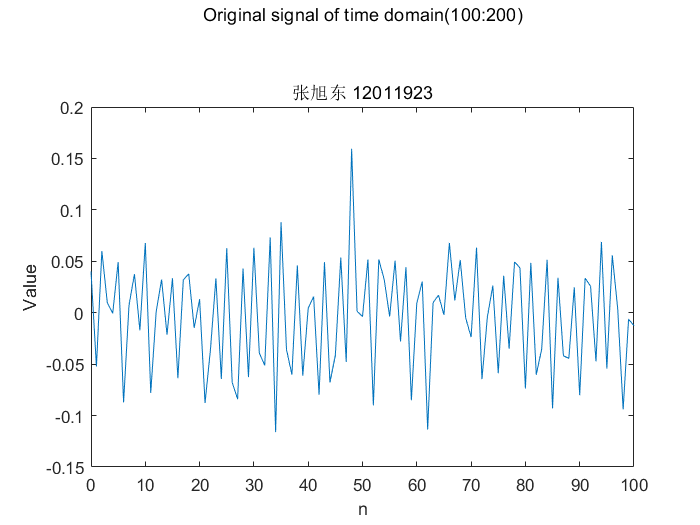


%7.4.2
load pcm.mat
sound(pcm);
figure
plot(0:100,pcm(100:200));
xlabel("n");
ylabel("Value");
title(["Original signal of time domain(100:200)" newline "张旭东 12011923"]);

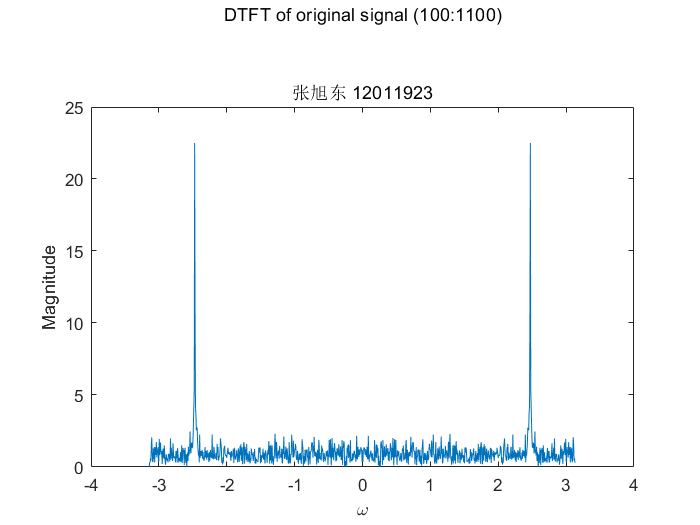


[Xofpcm,wofpcm]=DTFT(pcm(100:1100),1024);
plot(wofpcm,abs(Xofpcm));
xlabel("\omega");
ylabel("Magnitude");
title(["DTFT of original signal (100:1100)" newline "张旭东 12011923"]);




[Xmaxofpcm,Imaxofpcm]=max(abs(Xofpcm));
thetaofpcm1=-pi+(Imaxofpcm-1)*2*pi/1024;
disp(thetaofpcm1);

   -2.4728




thetaofpcm2=3146/8000*2*pi;
disp(3146/8000*2*pi)

    2.4709



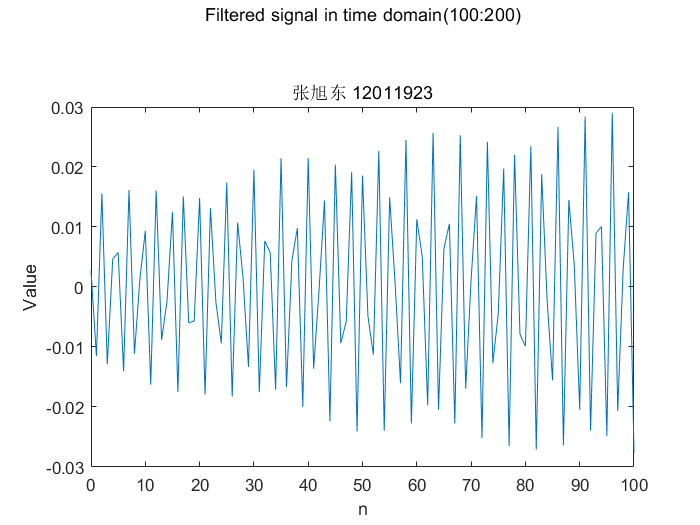


yofpcm=IIRfilter(pcm,thetaofpcm2,0.995);
sound(yofpcm);

plot(0:100,yofpcm(100:200));
xlabel("n");
ylabel("Value");
title(["Filtered signal in time domain(100:200)" newline "张旭东 12011923"]);

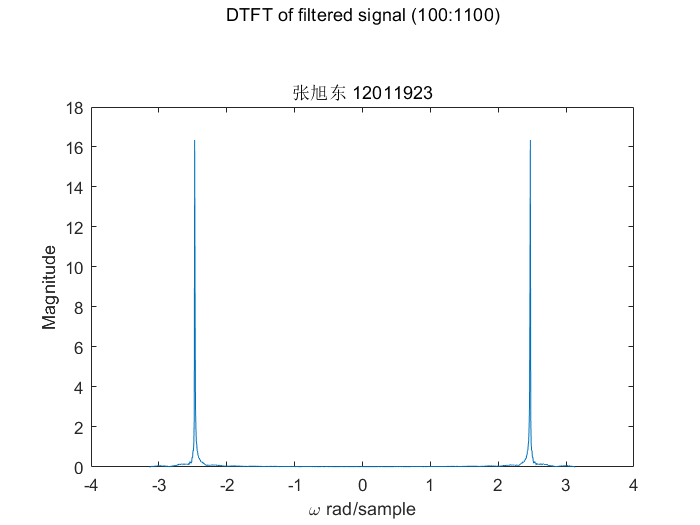


[Xoffilteredpcm,woffilteredpcm]=DTFT(yofpcm(100:1100),0);
plot(woffilteredpcm,abs(Xoffilteredpcm));
xlabel("\omega rad/sample");
ylabel("Magnitude");
title(["DTFT of filtered signal (100:1100)" newline "张旭东 12011923"]);

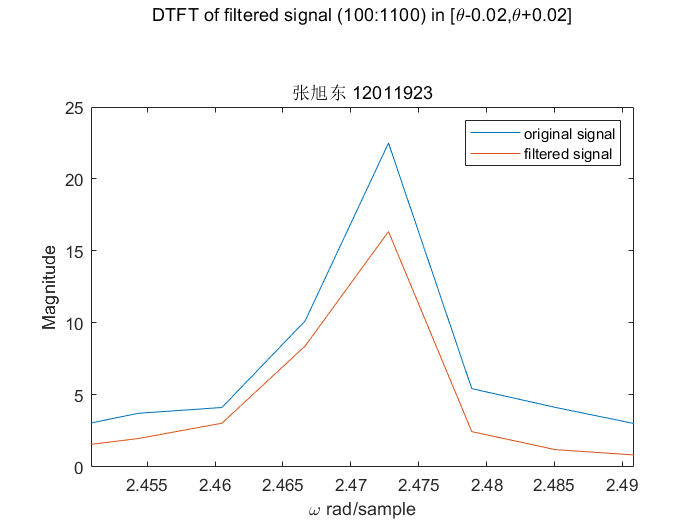


plot(wofpcm,abs(Xofpcm));
hold on;
plot(woffilteredpcm,abs(Xoffilteredpcm));
legend("original signal","filtered signal");
axis([thetaofpcm2-0.02 thetaofpcm2+0.02 0 25]); 
xlabel("\omega rad/sample");
ylabel("Magnitude");
title(["DTFT of filtered signal (100:1100) in [\theta-0.02,\theta+0.02]" newline "张旭东 12011923"]);

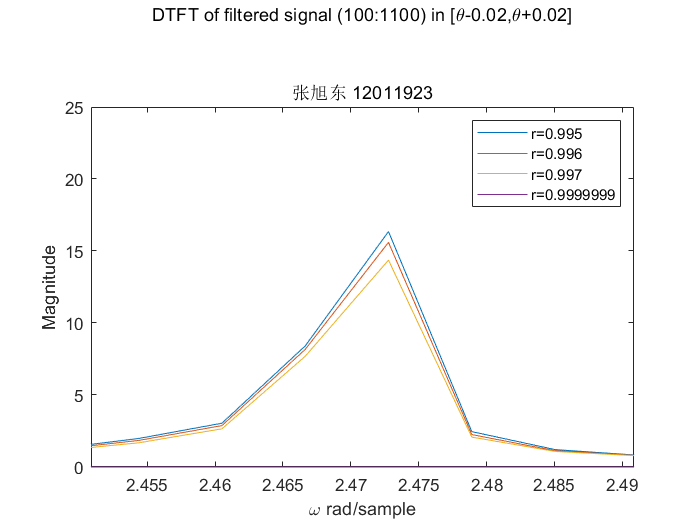


figure
yofpcm1=IIRfilter(pcm,thetaofpcm2,0.996);
[Xoffilteredpcm1,woffilteredpcm1]=DTFT(yofpcm1(100:1100),0);
yofpcm2=IIRfilter(pcm,thetaofpcm2,0.997);
[Xoffilteredpcm2,woffilteredpcm2]=DTFT(yofpcm2(100:1100),0);
yofpcm3=IIRfilter(pcm,thetaofpcm2,0.9999999);
[Xoffilteredpcm3,woffilteredpcm3]=DTFT(yofpcm3(100:1100),0);
plot(woffilteredpcm,abs(Xoffilteredpcm));hold on;
plot(woffilteredpcm1,abs(Xoffilteredpcm1));hold on;
plot(woffilteredpcm2,abs(Xoffilteredpcm2));hold on;
plot(woffilteredpcm3,abs(Xoffilteredpcm3));
legend("r=0.995","r=0.996","r=0.997","r=0.9999999");
axis([thetaofpcm2-0.02 thetaofpcm2+0.02 0 25]); 
xlabel("\omega rad/sample");
ylabel("Magnitude");
title(["DTFT of filtered signal (100:1100) in [\theta-0.02,\theta+0.02]" newline "张旭东 12011923"]);

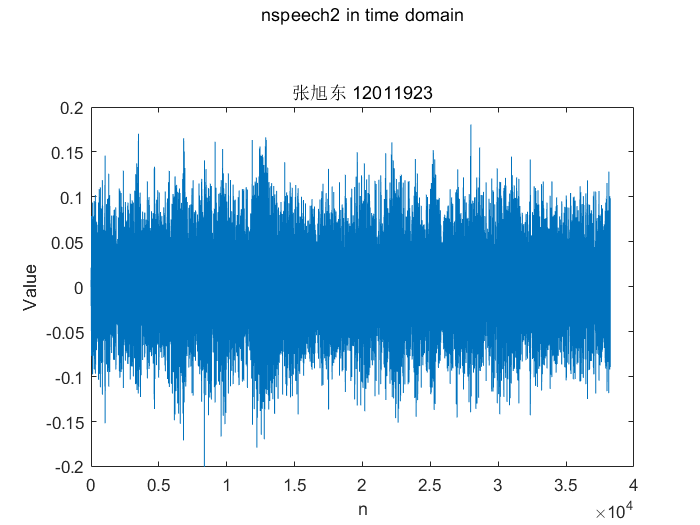




%7.5
load nspeech2.mat
sound(nspeech2);
figure
plot(nspeech2);
xlabel("n");
ylabel("Value");
title(["nspeech2 in time domain" newline "张旭东 12011923"]);

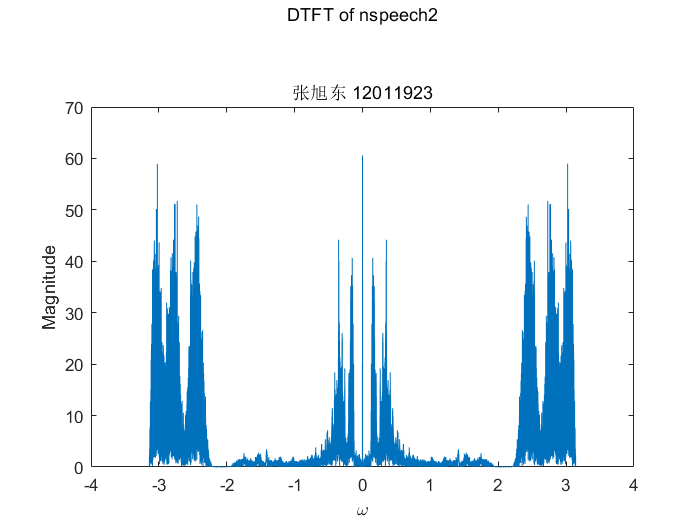


[Xofnsppech2,wofnspeech2]=DTFT(nspeech2,0);
plot(wofnspeech2,abs(Xofnsppech2));
xlabel("\omega");
ylabel("Magnitude");
title(["DTFT of nspeech2" newline "张旭东 12011923"]);

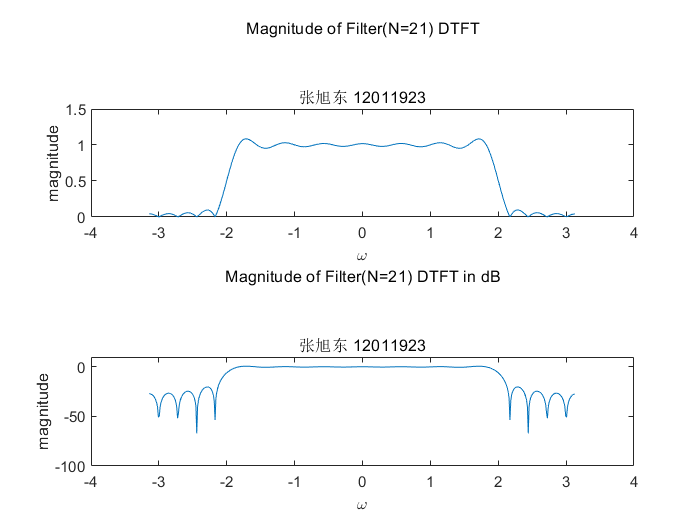


%7.6
N1=21;
h1=LPFtrunc(N1);
[XofN1,wofN1]=DTFT(h1,512);
figure
subplot(2,1,1);
plot(wofN1,abs(XofN1));
xlabel("\omega");
ylabel("magnitude");
axis([-4 4 0 1.5]);
title(["Magnitude of Filter(N=21) DTFT" newline "张旭东 12011923"]);
subplot(2,1,2);
plot(wofN1,20*log10(abs(XofN1)));
axis([-4 4 -100 10]);
xlabel("\omega");
ylabel("magnitude");
title(["Magnitude of Filter(N=21) DTFT in dB" newline "张旭东 12011923"]);

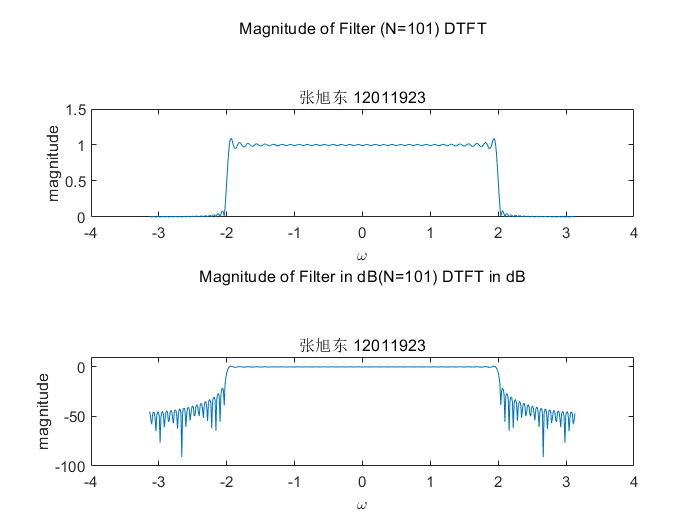


N2=101;
h2=LPFtrunc(N2);
[XofN2,wofN2]=DTFT(h2,512);
figure
subplot(2,1,1);
plot(wofN2,abs(XofN2));
axis([-4 4 0 1.5]);
xlabel("\omega");
ylabel("magnitude");
title(["Magnitude of Filter (N=101) DTFT" newline "张旭东 12011923"]);
subplot(2,1,2);
plot(wofN2,20*log10(abs(XofN2)));
axis([-4 4 -100 10]);
xlabel("\omega");
ylabel("magnitude");
title(["Magnitude of Filter in dB(N=101) DTFT in dB" newline "张旭东 12011923"]);

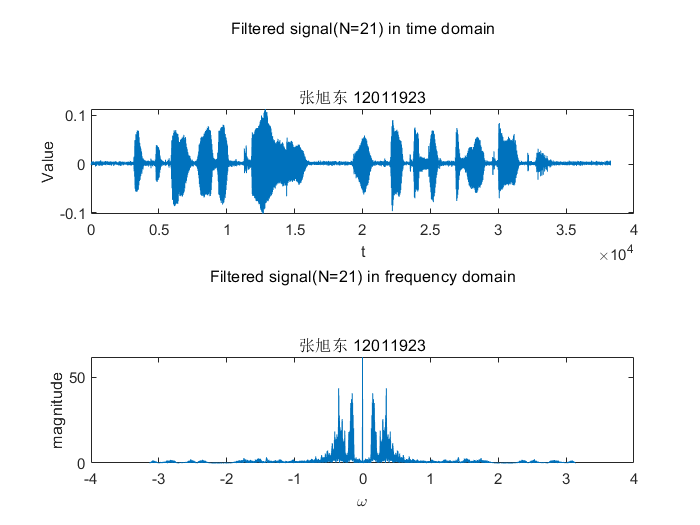




filteredsignalN1=conv(nspeech2,h1);
sound(filteredsignalN1*2);
figure;
subplot(2,1,1);
plot(filteredsignalN1);
xlabel("t");
ylabel("Value");
title(["Filtered signal(N=21) in time domain" newline "张旭东 12011923"]);
[XoffilteredsignalN1,woffilteredsignalN1]=DTFT(filteredsignalN1,0);
subplot(2,1,2);
plot(woffilteredsignalN1,abs(XoffilteredsignalN1));
xlabel("\omega");
ylabel("magnitude");
title(["Filtered signal(N=21) in frequency domain" newline "张旭东 12011923"]);

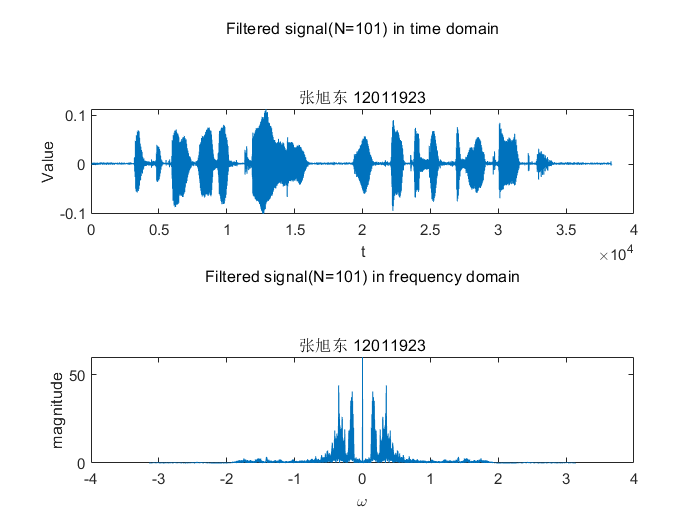


filteredsignalN2=conv(nspeech2,h2);
sound(filteredsignalN2*2);
figure;
subplot(2,1,1);
plot(filteredsignalN2);
xlabel("t");
ylabel("Value");
title(["Filtered signal(N=101) in time domain" newline "张旭东 12011923"]);
[XoffilteredsignalN2,woffilteredsignalN2]=DTFT(filteredsignalN2,0);
subplot(2,1,2);
plot(woffilteredsignalN2,abs(XoffilteredsignalN2));
xlabel("\omega");
ylabel("magnitude");
title(["Filtered signal(N=101) in frequency domain" newline "张旭东 12011923"]);